start_toolkit;

EPANET-MATLAB Toolkit Paths Loaded.


d = epanet('Group_13W.inp');

EPANET version {20305} loaded (EMT version {v2.3.5.2 - Last Update: 03/03/2026}).
<a href = "https://doi.org/10.5281/zenodo.831493">Publication DOI: 10.5281/zenodo.831493</a>
Loading File "Group_13W.inp"...
Input File "Group_13W.inp" loaded successfully.


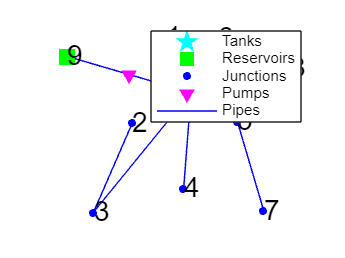

ans =   Axes with properties:

             XLim: [-3.5685e+03 7.6412e+03]
             YLim: [3.5182e+03 9.3414e+03]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


d.plot

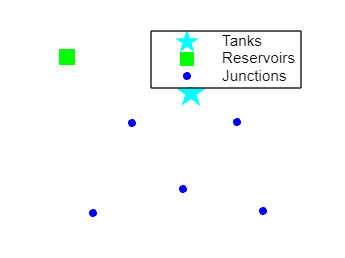

ans =   Axes with properties:

             XLim: [-3.5685e+03 7.6412e+03]
             YLim: [3.5182e+03 9.3414e+03]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


d.plot('nodes', 'yes', 'fontsize', 12)

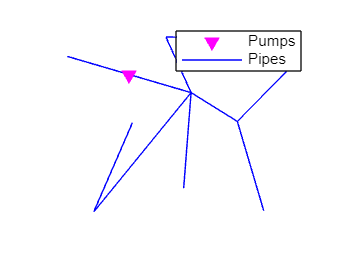

ans =   Axes with properties:

             XLim: [-3.5685e+03 7.6412e+03]
             YLim: [3.5182e+03 9.3414e+03]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


d.plot('links', 'yes', 'fontsize', 12)

d.plot('linksindex', 'yes', 'fontsize',8);

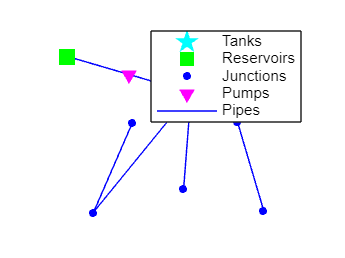

d.plot('nodesindex', 'yes', 'fontsize',14);

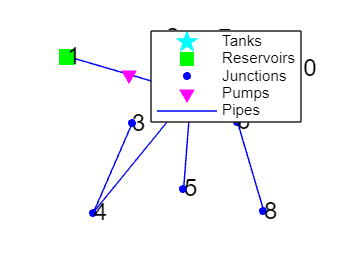

d.plot('line', 'no');

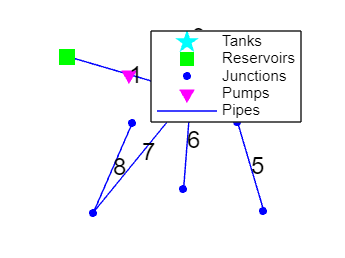

d.plot('point', 'no');

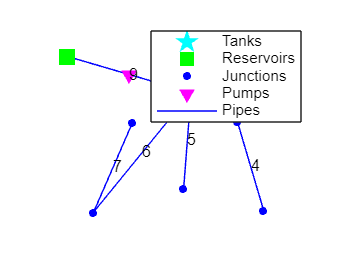

d.plot('legend', 'hide');

linkSet1 = d.getLinkNameID(1:4);
colorLinkSet1 = repmat({'r'},1,length(linkSet1));
linkSet2 = d.getLinkNameID([5,6,7,8]);
colorLinkSet2=repmat({'g'},1,length(linkSet2));
d.plot('highlightlink',[linkSet1 linkSet2],'colorlink',[colorLinkSet1 colorLinkSet2])

ans =   Axes with properties:

             XLim: [-3.5685e+03 7.6412e+03]
             YLim: [3.5182e+03 9.3414e+03]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


hrs = 100;
d.setTimeSimulationDuration(hrs*3600);
tic;
hyd_res_1 = d.getComputedTimeSeries

hyd_res_1 = struct with fields:
              Time: [101×1 double]
          Pressure: [101×10 single]
            Demand: [101×10 single]
              Head: [101×10 single]
       NodeQuality: [101×10 single]
              Flow: [101×9 single]
          Velocity: [101×9 single]
          HeadLoss: [101×9 single]
            Status: [101×9 single]
           Setting: [101×9 single]
      ReactionRate: [101×9 single]
    FrictionFactor: [101×9 single]
       LinkQuality: [101×9 single]
      EnergyReport: [1×1 struct]
         StatusStr: {101×9 cell}


time_1 = toc;
tic;
hyd_res_3 = d.getComputedHydraulicTimeSeries('time', 'flow', 'pressure'); 
time_3 = toc;
% etstep = 3600;
% d.setTimeReportingStep(etstep);
% d.setTimeHydraulicStep(etstep);
% d.setTimeQualityStep(etstep);
tic;
d.openHydraulicAnalysis;
d.initializeHydraulicAnalysis;
tstep=1;P=[];T_H=[];
while (tstep>0)
    t=d.runHydraulicAnalysis;
    P=[P; d.getNodePressure];
    T_H=[T_H; t];
    tstep=d.nextHydraulicAnalysisStep;
end
d.closeHydraulicAnalysis;
time_4 = toc;